# EKF prediction Step

Kalman filter represents  robot state (pose) at time t by the mean $\mu$ and the covariance $\Sigma$.  These parameters represent the mean and variance of a [multivariate Gaussian distribution](https://la.mathworks.com/help/stats/multivariate-normal-distribution.html). So We can say that after execute EKF we will have multiple possible poses defined by $\Sigma$ however the most likely is   $\mu$.

The state vector is a pose defined by $\left\lbrack x;\;\;y;\;\;\theta \right\rbrack$ and Covariance is a n x n matrix (Where n is the size of state vector ). Through EKF   $\mu$ and  $\Sigma$ are recalculated to get the best state prediction.

Vector state at time $t$ is represented by :  $\vec{x_t } =\left\lbrack \begin{array}{c}
x_t \\
y_t \\
\theta_t 
\end{array}\right\rbrack$

The extended  kalman Filter is divided in two steps, the first one is the Prediction and the second is Update.

### Prediction step:  

#### 
$$\vec{x_t } =g\left({\overrightarrow{x} }_{t-1} ,\overrightarrow{u} \right)+\gamma$$


Where:  

            Function $g$ is a nonlinear function that calculate new state vector. $g\left({\overrightarrow{x} }_{t-1} ,u\right)=\left\lbrack \begin{array}{c}
\theta_t +u_{\theta } \\
x_{t-1} +u_d \cos \left(u_{\theta } \right)\\
y_{t-1} +u_d \sin \left(u_{\theta } \right)
\end{array}\right\rbrack$

           ${\vec{x} }_{t-1}$ is the last state vector.

            $\overrightarrow{u}$  is a control command $\overrightarrow{u} =\left\lbrack \begin{array}{c}
\theta \\
d
\end{array}\right\rbrack \;\;\textrm{indicates}\;\;\textrm{turn}\;\textrm{angle}\;\textrm{and}\;\textrm{distance}$. 

            $\gamma$ represents the mean of gaussian noise function that we don't know because that noise depend on physical environment.

#### 
$$\Sigma_t =G\Sigma_{t-1} G^T +Q$$


Where: 

            $G$ is the jacobian of function $g$ so $G=\left\lbrack \begin{array}{ccc}
1 & 0 & -u_d \sin \left(\theta_t +u_{\theta } \right)\\
0 & 1 & u_d \cos \left(\theta_t +u_{\theta } \right)\\
0 & 0 & 1
\end{array}\right\rbrack$ 

            $Q$ represent a square  n x n matrix (Where n is the size of state vector )   which is the covariance of noise environment. $Q=\left\lbrack \begin{array}{ccc}
\Sigma_{\textrm{xx}}  & \Sigma_{\textrm{xy}}  & \Sigma_{x\theta } \\
\Sigma_{\textrm{yx}}  & \Sigma_{\textrm{yy}}  & \Sigma_{y\theta } \\
\Sigma_{\theta x}  & \Sigma_{\theta y}  & \Sigma_{\theta \theta } 
\end{array}\right\rbrack$

Since a mobile robot usually does not execute commands like $\overrightarrow{u}$ we change to sampling approach.

Sampling approach defines a function that It accepts the latest  state vector${\vec{x} }_{t-1}$, odometry readings  in time $t-1$ and $t$ as input, and outputs a random $\vec{x_t }$ distributed according to $g$.

We will show how to code this concepts using hypothetical data as follow:

Define a odometry reading at time $t-1$

o_1 = [ 2; 2; 0 ];

Define a odometry reading at time $t$

o = [ 5; 5; .7 ];

Define the last state vector

x_1 = [ 3; 3 ; 0];

Alpha array is defined by :

                    alpha1  Specifies the expected noise in odometry's rotation estimate from the rotational component of the robot's motion.

                    alpha2  Specifies the expected noise in odometry's rotation estimate from translational component of the robot's motion.

                    alpha3  Specifies the expected noise in odometry's translation estimate from the translational component of the robot's

                    alpha4  Specifies the expected noise in odometry's translation estimate from the rotational component of the robot's motion.

alpha= [ 0.1 0.001 0.001 0.001 ]; %These values are diferent for any robot. In this simulations depends on added noise.

Number of samplings

n = 500;

Define a matrix to store all samplings

samples = zeros(3,n); 

Get a random sampling by function sampleOdometry (it returns  a state vector $\overrightarrow{x}$and comand $\overrightarrow{u}$ ) and show all samplings.

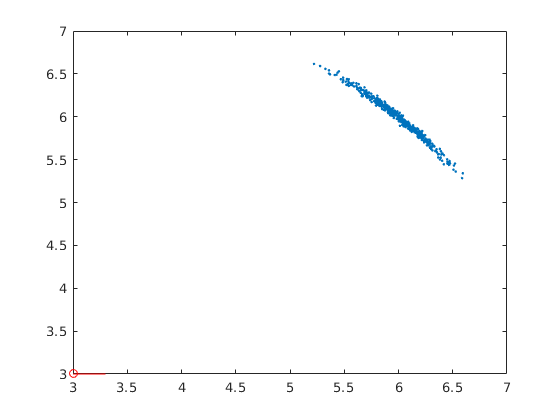

for i=1:n
  [sv, u ] = sampleOdometry(o_1,o,x_1,alpha);
  samples(1,i) =  sv(1); 
  samples(2,i) =  sv(2); 
  samples(3,i) =  sv(3); 
end

r = 0.3;%robot radio just for visualization
plot( samples(1,:) , samples(2,:),'.');
hold on
plot(x_1(1), x_1(2), 'ro')
plot([x_1(1), x_1(1) + r*cos(x_1(3))], [x_1(2), x_1(2) + r*sin(x_1(3))], 'r-' )
%Uncomment to show posible final robot poses
% for i=1:n
%   plot([samples(1,i) , samples(1,i) + r*cos(samples(3,i))], [samples(2,i), samples(2,i) + r*sin(samples(3,i))], 'r-' )
% end
hold off

In figure above We can see( in red ) the start pose of the robot then It execute $\overrightarrow{u}$ command (which change in every sampling). The last command sampling was:

The robots turns 

u(1)

ans = 0.9202

Then the robot  move forward 

u(2)

ans = 4.2679

Because  alpha1 is  greater than other alphas the resulting sampling show  a density in arc form because  is more probably that the robot makes drifting  while  robot turns.

# Practice

Increase alphas one by one and compare graphs to understand how each one affects the sampling.

--------------------

Finally prediction step is defined (hypothetical data) by :



Q = [0.01  0.00  0.00;  % Each variable is only related itself.
     0.00  0.01  0.00; 
     0.00  0.00  0.01];

sigma = [0 0 0;  %Covariance matrix start with all elements zero
         0 0 0; 
         0 0 0];

[sv, u] = sampleOdometry(o_1,o,x_1,alpha); 

 %Jacobian of function g(sv,u)
G = [ 1 0  -u(2)*sin(u(1));
      0 1   u(2)*cos(u(1));
      0 0         1       ];
  
sigma =  G*sigma*G.' + Q;

The above will use in next lesson.


initPose = [ 0.5; 0.5; 1.5707]; % [x ; y ; theta]   
goalPose = [2; 2.5;0];

R = 0.1; 
L = 0.12; 

viz = Visualizer2D;
viz.mapName = 'map';
viz.robotRadius = L; 
mobileRobot = DifferentialDrive(R,L);


Prepare map  to calculate path

                       
[map, mapDilatation]  = generateAugmentedMap(which('world1.png'), 0.1, 10, L); %[path, treshold, scale,robotRadio]
                
[pthObj, solnInfo] = getPathRRT(mapDilatation,initPose,goalPose,0.2,.1,0.2,30000); %[map,initPose,goalPose,MinTurningRadius,ValidationDistance,MaxConnectionDistance,MaxIterations]
              
[controller] = controllerPP(pthObj,0.05,0.1,pi/6); %[pthObj,LookaheadDistance,DesiredLinearVelocity,MaxAngularVelocity)]

Execute simulation.

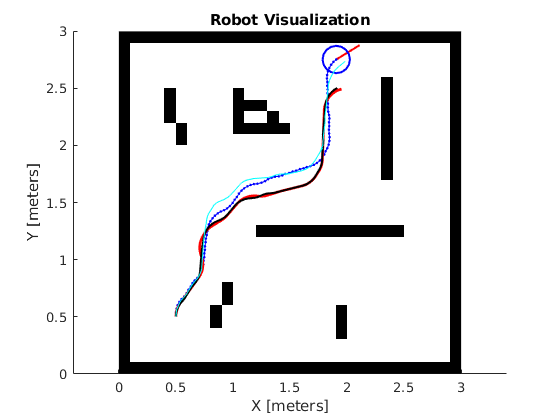

Q = [0.001  0.00  0.00;  % Each variable is only related itself.
     0.00  0.001  0.00; 
     0.00  0.00  0.001];

sigma = [0 0 0;  %Covariance matrix start with all elements zero
         0 0 0; 
         0 0 0];

currentPose = initPose;

varianceV= 0.01; %.3 
varianceW= 0.04; % .1


[sampleTime,tVec,r] = simulTime(0.3,38);
odom_pose = zeros(3,numel(tVec));
odom_pose(:,1) = initPose;

svArray = zeros(3,numel(tVec));
svArray(:,1) = initPose;


alpha= [ 0.5 0.501 20.501 0.501 ];

for idx = 2:numel(tVec) 
      
    if( sqrt( (odom_pose(1,idx-1)-pthObj.States(end,1))^2 + (odom_pose(2,idx-1)-pthObj.States(end,2))^2 )  < L/2  )
       break
    end
    
    [v,w,lookAheadPt] = controller(odom_pose(:,idx-1));

    [wL,wR] = inverseKinematics(mobileRobot,v ,w);
    
    % Store each pose computed by odometry
    odom_pose(:,idx) =  computeOdometry(R,L,wR,wL,sampleTime ,odom_pose(:,idx-1));
    
    [sv, u] = sampleOdometry(odom_pose(:,idx-1),odom_pose(:,idx),svArray(:,idx-1),alpha);
    
    svArray(:,idx) = sv;
    
     %Jacobian of function g(sv,u)
    G = [ 1 0  -u(2)*sin(u(1));
          0 1   u(2)*cos(u(1));
          0 0         1       ];
    sigma =  G*sigma*G.' + Q;
    
    
  
    v = v  + abs(normrnd(0,varianceV));
    w = w + normrnd(0,varianceW);
    bodyV = [v ;0;w];    % Body velocities [vx;vy;w]  vy = 0 because the differential robot can not move in y axis.
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
    
     
    % Update visualization
    viz(currentPose);
    hold on
    h2 = error_ellipse(sigma(1:2,1:2), svArray(1:2,idx) );
    if idx ==2
        interpolate(pthObj,300)  
        plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2) % Red Path compute by RTT*
    end
    
    %Wait for visualization rate
    waitfor(r);
    set(h2,'Visible','off')
end


hold on

plot(odom_pose(1,1:idx-1),odom_pose(2,1:idx-1),'k-','LineWidth', 1.5); %Black Odometry reported by robot sensors
plot(svArray(1,1:idx-1),svArray(2,1:idx-1),'c'); % Cyan is trajectory reported by Prediction step of Kalman Filter   

hold off

                                                    Path compute by RTT* in red.

                                                    Odometry reported by robot sensors in Black 

                                                    Cyan is trajectory reported by Prediction step of Kalman Filter  

**As you can see in plot above,  the trajectory of prediction step is  better than the odometry which is similar to path generated by path planning, this hapend because the sampling approach and alphas values. The elipses shows the uncertainty (**$\Sigma$**) of the predicted pose where the mean (**$\mu \;$**)  is the state vector computed by sampleOdometry fuction.  If the robot knows more accurate its real pose  is able to correct its movements to arrive to the goal.**

**The objetive is to reduce  uncertanty and imporve the state vector prediction, this will be done by *****Update step of EKF  in next lesson.  ***

# ***Practice***

***Change pose from ***odom_pose*** to ***svArray*** in controller  (Line 92 ) then execute script. Analize the result.***

***Note: elipses are plot by *** [AJ Johnson](https://la.mathworks.com/matlabcentral/profile/authors/869398)